# Problema 1 - Simulación de Montecarlo

clear;
close all;
% Global settings
warning('off'); % warnings about rank 
figure('Renderer', 'painters', 'Position', [10 10 900 600]); % figures size

El propósito de este ejercicio es utilizar de manera eficiente ciertos comandos de  Matlab tales como matrices, loops, while, plot y subplot. Se aplican diversos conocimientos econométricos y se han desarrollado  algoritmos de la forma más eficientes posible. Las funciones trabajadas se pueden acceder aquí:

- [xx.m](matlab:open('./xx.m'))

- [plotxx.m](matlab:open('./plotxx.m'))

- [random.m](matlab:open('./random.m'))

- [algoritmo.m](matlab:open('./algoritmo.m'))

- [algoritmo2.m](matlab:open('./algoritmo2.m'))

El modelo de estudio está dado por:


$$y=\beta_0 +{\beta_1 \cdot \;x}_1 +{\beta_2 \cdot \;x}_2 +{\beta_3 \cdot \;x}_3 +{\beta_4 \cdot \;x}_4 +{\beta_5 \cdot \;x}_5 +{\beta_5 \cdot \;x}_5 +{\beta_6 \cdot \;x}_6 +\epsilon \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$


## (a) Distribución de variables 

### 0. Parámetros 

r = 1000; % Muestra de tamaño 1000
c = 1;
x = rand(r,c);
x_i = randn(r,c);

#### 1. $x_{1\;} ~U\left(1,8\right)\;$

x1 = x*(8-1)+1;

#### 2. $x_2 ~N\;\left(3,4\right)$

Se debe construir con una matriz de números aleatorios con distribución normal, con media 3 y desvío 4 (con randn)

x2 = x_i*4 + 3;

#### 3. $x_3 ~{X_{100} }^2$

 Chi cuadrado de 100 gl usando randn que genere una normal de  media 0 y varianza 1

x3 = 100*(x_i.^2);

#### 4. $x_4 ~{\left(t\;\textrm{student}\right)}_2$

 t student 2 gl

x4a = 0;
for i = 1:2
    x4a = x4a + randn(r,c).^2;
    i = i+1;
end

x4 = x_i./sqrt(x4a/2);

#### 5. $x_{5\;} ~\textrm{una}\;\textrm{mixtura}\;\textrm{tal}\;\textrm{que}\;\textrm{el}\;50%\;\textrm{de}\;\textrm{las}\;\textrm{veces}\;\textrm{se}\;\textrm{comporta}\;\textrm{como}\;x_{2\;} \;y\;\textrm{el}\;50%\;\textrm{de}\;\textrm{las}\;\textrm{veces}\;\textrm{como}\;x_3 \;$

Para generar esta distribución utilizaré mi variable aleatoria adicional (x) y a partir de ella seleccionaré una muestra donde con un 50% de probabilidad se recupere el valor de x2 o en caso contrario x3

x5 = zeros(r,c);

for i = 1:r
    if x (i,1) < 0.5
        x5(i,1) = x2(i, 1);
    else
        x5(i) = x3(i,1);
    end
    i = i+1;
end

#### 6. $x_6 \;\;\textrm{es}\;\textrm{un}\;\textrm{promedio}\;\textrm{entre}\;x_{4\;\;} \;y\;x_5 \;\textrm{más}\;\textrm{un}\;\textrm{error}\;\textrm{normal}\;\textrm{con}\;\textrm{media}\;0\;\;y\;\textrm{desvío}\;0\ldotp 1\;$

X6: promedio de X4 y X5 mas un error normal con media cero y desvio 0.0001.

error = x_i* 0.1;
x6 = (x4+x5)/2 + error;

#### 7. $y~\exp \left(0\ldotp 6\right)\;$

% --> 1-rand = exp(-lamda*x) --> log(1-rand) = (-lamda*x) -->
% log(1-rand)/-lamda = x
y = log(1-x)/(-0.6);

#### 8. $\;\epsilon ~N\left(0,1\right)$

epsilon = x_i;

Se ha creado una función xx.m que construye las distribuciones de las variables indicadas, y que recibe como input el número de observaciones. Con la función plotxx.m graficaremos estas distribuciones en un histograma

mm = xx(1000,1);
plotxx(mm, 1000,1)

Además también se muestra la distribución de **y** y el **error**

figure(2)
subplot(3,2,1)
histogram(y,100)
title('Y')
subplot(3,2,2)
histogram(epsilon,100)
title('Error')
hold off

### (b) Genere 1000 muestras de tamaño n = 100 para todas la variables x

x_i = randn(100,1000)

x_i =    -0.2720    0.1553   -0.3770    1.0696   -0.5956   -0.1079    0.3474   -0.6334   -0.0487   -1.5218    0.1461   -1.5117   -0.6247   -0.9243   -0.3788   -0.4817    0.6746    0.5005    0.1883    0.6552    1.4051   -0.1374   -1.8297   -0.9159   -0.7489    0.0301    1.5755    0.2464   -0.9989   -0.5887    0.1860    1.3317    0.2952    1.0289    1.9416   -1.5075    0.6298    0.4140   -0.2199    1.7680    0.0585    1.7580   -0.3935   -0.7251    1.8565   -0.0774   -0.7961   -1.0519    0.6773    1.5269
   -0.9596    0.5499    0.3887   -0.5196   -0.2508    0.4376    0.4582   -0.6959    0.8516    1.4150    0.2727   -0.6009   -0.4685   -1.5541    0.5649   -0.1442    0.5190   -0.6092   -0.7720    0.3441    0.0111    1.0876    1.6149    0.6435   -0.8630   -0.0718   -1.4835   -1.0511    1.4235   -0.0118   -0.0837    0.7928    0.9877    0.3077   -0.4526    0.4636    0.0429   -0.1065    0.9431    0.4856   -0.8800    1.1693   -0.0488    0.0687    0.3449   -2.7986   -0.9602    0.5072    0.5849   

x = rand(100,1000)

x =     0.2078    0.9048    0.3286    0.6572    0.8834    0.9197    0.9779    0.9924    0.3449    0.2164    0.3312    0.0114    0.9110    0.7959    0.1294    0.8285    0.8508    0.2295    0.8195    0.9126    0.9793    0.0975    0.4693    0.7646    0.4146    0.2246    0.8804    0.1766    0.6563    0.8108    0.3879    0.8651    0.4166    0.8780    0.7821    0.3869    0.3624    0.2739    0.1196    0.6068    0.7973    0.9559    0.3469    0.0335    0.6719    0.2880    0.2788    0.7959    0.2831    0.7501
    0.9898    0.1602    0.8020    0.0652    0.8384    0.1964    0.2477    0.1391    0.2645    0.4992    0.1837    0.3426    0.5717    0.2108    0.9742    0.4108    0.3636    0.2976    0.9152    0.9784    0.5030    0.3567    0.7954    0.4614    0.5648    0.3139    0.1879    0.5501    0.6827    0.5504    0.2621    0.9263    0.9124    0.3498    0.2784    0.7483    0.0935    0.3454    0.4198    0.1736    0.6923    0.1786    0.2218    0.4215    0.6022    0.5578    0.3316    0.3862    0.1044    0

### (c ) Crear función

Cree la funcion random que recibe como inputs el número de muestras y el tamaño de cada muestra. Además, debe entregar como output una matriz que compile todas las variables x(1−6) junto con entregar un subplot que indique como distribuye cada una de las variables (histograma).

random(100,1000)

ans = 1.0e+03 *

    0.0013    0.0013    0.0045    0.0047    0.0055    0.0047    0.0021    0.0072    0.0013    0.0034    0.0059    0.0037    0.0048    0.0053    0.0065    0.0027    0.0068    0.0010    0.0063    0.0033    0.0028    0.0052    0.0056    0.0010    0.0017    0.0075    0.0046    0.0041    0.0049    0.0027    0.0042    0.0054    0.0078    0.0054    0.0035    0.0075    0.0056    0.0071    0.0055    0.0018    0.0027    0.0012    0.0028    0.0077    0.0060    0.0015    0.0071    0.0065    0.0013    0.0029
    0.0026    0.0069    0.0031    0.0060    0.0033    0.0018    0.0022    0.0015    0.0019    0.0071    0.0076    0.0059    0.0071    0.0032    0.0070    0.0024    0.0014    0.0028    0.0060    0.0052    0.0023    0.0065    0.0031    0.0014    0.0047    0.0043    0.0023    0.0038    0.0050    0.0021    0.0040    0.0045    0.0076    0.0029    0.0068    0.0030    0.0041    0.0014    0.0028    0.0048    0.0022    0.0023    0.0041    0.0068    0.0041    0.0067    0.0041    0.0017  

X = random(100, 1000);

(d) Compute la media, mediana, mínimo, máximo, varianza y percentiles 25 y 75 de las muestras obtenidas.

La tabla se lee como que cada fila corresponde a los estadísticos descriptivos de cada x_n

statistics = [ mean(X(:,1:1000:6000))' std(X(:,1:1000:6000))'  min(X(:,1:1000:6000))' max(X(:,1:1000:6000))' median(X(:,1:1000:6000))' prctile(X(:,1:1000:6000),25)' prctile(X(:,1:1000:6000),75)']

statistics =     4.7001    2.0812    1.1620    7.9631    4.8678    2.9692    6.5360
    2.7870    3.9903   -6.1136   11.1098    2.7745    0.0640    5.6551
   98.8051  119.6668    0.0002  519.1137   49.1089    7.0975  159.9057
   -0.0600    1.0032   -1.0000    1.0000   -1.0000   -1.0000    1.0000
   54.8542  100.3070   -5.3336  519.1137    6.3363    2.3476   51.2967
   27.3918   50.1399   -3.3751  258.8290    3.7516    0.6585   26.2200


### OLS

Ahora, dado que se conoce la distribución de cada una de las variables x(1−6) y el vector y, aplicando la metodología OLS, estimar a los parámetros β1−6.

Sabemos que para poder calcular los coeficientes de regresión debemos utilizar la matrix de los $X_n$ para luego calcular $\hat{\beta} ={\left(X^{\prime } X\right)}^{-1} X^{\prime } \;y$.

Ahora bien, en **Matlab **es más rápido resolver como $\hat{\beta} ={\left(\textrm{Xy}\right)}^{\prime }$

#### (e) Compute el vector3 de estimadores  $\beta {\;}_{7\textrm{x1}}$ para una muestra arbitraria.

mm = [ones(1000,1) mm]

mm = 1.0e+03 *

    0.0010    0.0011   -0.0021    0.1631   -0.0036   -0.0021   -0.0030
    0.0010    0.0023    0.0058    0.0497    0.0010    0.0058    0.0035
    0.0010    0.0053    0.0111    0.4086    0.0019    0.4086    0.2054
    0.0010    0.0067   -0.0007    0.0841   -0.0013    0.0841    0.0413
    0.0010    0.0015    0.0022    0.0043   -0.0004    0.0022    0.0009
    0.0010    0.0069   -0.0054    0.4362   -0.0024    0.4362    0.2167
    0.0010    0.0038    0.0023    0.0029   -0.0010    0.0023    0.0006
    0.0010    0.0020    0.0006    0.0369   -0.0007    0.0006   -0.0001
    0.0010    0.0048    0.0033    0.0005    0.0001    0.0005    0.0003
    0.0010    0.0048    0.0051    0.0265    0.0005    0.0265    0.0136


%beta_1 = inv(mm'*mm)*mm'*y
beta_1 = (mm\y)'

beta_1 =     1.6549   -0.0124    0.0081    0.0003    0.0182    0.0000         0


#### (f) Compute una matriz que contenga los vectores de estimadores $\beta_{\textrm{ols}}$ para 1000 muestras

for i=1:1000
    X = [(ones(100,1)) xx(100,1)];
    y = log(1-rand(100,1))/(-0.6);
    beta_2(i,:) = (X\y)';
end 

Podemos representar los coeficientes de regresión de la siguiente manera

figure(5)
for j=1:7
    subplot(3,3,j);
    histogram(beta_2(:,j),100);
    title(['\beta_',num2str(j-1)])
end 

g) Desarrolle un algoritmo que reciba como *input* el **tamaño de cada muestra (m)** y el** número de muestras (i)** y que entregue como *output* un **subplot** donde se observe la distribución de cada estimador $\beta_{\textrm{ols}} \;$ para cada figura asociada a cada tamaño de muestra. Utilice el vector $t\left\lbrack {10}^2 \;{10}^3 \;{10}^4 \;{10}^5 \right\rbrack$ para los distintos tamaños de muestras.

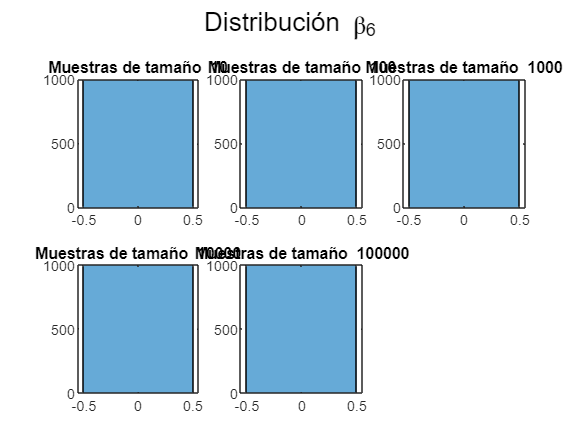

ans = struct with fields:
        ols_10: [1000×7 double]
       ols_100: [1000×7 double]
      ols_1000: [1000×7 double]
     ols_10000: [1000×7 double]
    ols_100000: [1000×7 double]


m = 1000;
t = [10 10^2 10^3 10^4 10^5];
algoritmo(t,m)

Responda: ¿Cómo distribuyen los estimadores? ¿En torno a que valor están centradas las distribuciones? ¿Por qué? Interprete y explique brevemente

En el caso de los $\beta_{o\;} ,\;\beta {\;}_2 \;y\;\beta_{4\;}$ podemos notar que las distribuciones están centradas en el cero,  y a medida que aumenta el tamaño de la muestra su distribución es cada vez más simétrica y con menor curtosis. En estos dos casos es notable como contrasta esto con muestras de tamaño 10, donde son mucho más asimétricas y hay presencia de outliers en valores  negativos en caso del intercepto, y en valores positivos en caso de el coeficiente 2. 

En el caso de $\beta_{1\;} \;\textrm{esta}\;\textrm{distribución}\;\textrm{no}\;\textrm{cambia}\;\textrm{mucho}\;\textrm{con}\;\textrm{el}\;\textrm{aumento}\;\textrm{del}\;\textrm{tamaño}\;\textrm{de}\;\textrm{la}\;\textrm{muestra}$. Mientras que en $\beta_{3\;} \;\;y\;\beta_{5\;\;} \textrm{las}\;\textrm{muestras}\;\textrm{de}\;\textrm{tamaño}\;\textrm{más}\;\textrm{pequeño}\;\textrm{tienen}\;\textrm{una}\;\textrm{curtosis}\;\textrm{notable}\;\textrm{que}\;\textrm{se}\;\textrm{va}\;\textrm{suavizando}\;a\;\textrm{medida}\;\textrm{que}\;\textrm{aumenta}\;\textrm{el}\;\textrm{tamaño}\;\textrm{de}\;\textrm{la}\;\textrm{muestra}\ldotp \;$

El caso de $\beta_{6\;}$tenemos un valor también centrado en el cero, pero casi único. Recordemos que esta variable se calculada con el promedio entre $x_{4\;y\;} \;x_5$ y estas dos tienen una distribución "espejo" donde su único valor que intersecta es el 0 (ver figuras iniciales). 

En términos generales, gracias a estas gráficas podemos notificar el poder que tienen las simulaciones de Montecarlo. Montecarlo es una metodología de estudio en la cual, con la generación de una gran cantidad de números aleatorios, podemos determinar el comportamiento de un sistema y/o el valor de distintas variables.

La idea básica detrás de usar Montecarlo es ejecutar simulaciones una y otra vez para obtener la distribución probabilística de una entidad pobabilística desconocida. Los métodos numéricos, como Montecarlo,  muchas veces son útiles cuando los métodos analíticos son muy difiíciles de resolver o la solución no existe. La razón: nos permite rescatar las **propiedades asintóticas **de la estimación de las regresiones. Y eso mismo estamos haciendo en estos ejercicios. 

### Estimación de coeficientes de regresión

A partir de la última pregunta estimaremos el vector** y** haciendo uso del vector $\hat{\;\beta {\;}_{\textrm{ols}} } \;$ [1 2 3 4 5 6 7]' y del vector de residuos $\epsilon ~N\left(0,1\right)$


$$y=X\beta \;+\epsilon$$


#### (h) De forma similar a lo desarrollado eb el ítem anterior, cree un algoritmo que entregue como output un subplot donde se observe la distribución de cada ${\hat{\;\beta \;} }_{\textrm{ols}}$ para cada tamaño de muestra distinta

ans = struct with fields:
        ols_10: [1000×7 double]
       ols_100: [1000×7 double]
      ols_1000: [1000×7 double]
     ols_10000: [1000×7 double]
    ols_100000: [1000×7 double]


algoritmo2(t,m)

¿En torno a que valores están centradas las distribuciones? ¿Porqué? Explique las diferencias respecto al inciso anterior

A diferencia del inciso anterior, las distribuciones no están centradas en el cero, sino que sus estimaciones están desviadas positivamente. La razón es que ahora, para calcular los coeficientes de regresión no utilizamos directamente los valores de la matriz de vectores de variables aleatorias, y su relación con el **y. **Si no que partimos prediciendo el  **y** con una perturbación normal ($\left.\epsilon ~N\left(0,1\right)\right)\;$y en donde, entonces tendremoa que nuestra variable real estará estimada con un error. Formalmente tenemos que :

$\epsilon =y-y^*$ donde $y^{*\;} \;\mathrm{es}\;\mathrm{la}\;\mathrm{variable}\;\mathrm{real}\;$

Luego tenemos que si bien el modelo original es 


$$y^* =\beta_0 +{\beta_1 \cdot \;x}_1 +{\beta_2 \cdot \;x}_2 +{\beta_3 \cdot \;x}_3 +{\beta_4 \cdot \;x}_4 +{\beta_5 \cdot \;x}_5 +{\beta_5 \cdot \;x}_5 +{\beta_6 \cdot \;x}_6 +u\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$


Nosotros estimamos un 


$$y=\beta_0 +{\beta_1 \cdot \;x}_1 +{\beta_2 \cdot \;x}_2 +{\beta_3 \cdot \;x}_3 +{\beta_4 \cdot \;x}_4 +{\beta_5 \cdot \;x}_5 +{\beta_5 \cdot \;x}_5 +{\beta_6 \cdot \;x}_6 +u+\epsilon \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$


Esto implica que tendremos ahora un error compuesto: uno conformado por el "error" que teóricamente tiene el modelo estimado y otro que le agregamos a la estimación. 

Notemos un punto importante y es que los estimadores no dejan de ser consistentes dado que el valor esperado del error sigue siendo cero.  El problema más bien estará en la varianza condicional del error en relación al X, y que esto se podrá notar claramente en las gráficas. Matemáticamente


$$\begin{array}{l}
\mathrm{Sea}\;v=\epsilon +u\;\\
\mathrm{Var}\left(v|X\right)=\mathrm{Var}\;\left(u+\epsilon \;|X\right)=\mathrm{Var}\left(u|X\right)+\mathrm{Var}\left(\epsilon \;|X\right)+2\mathrm{Cov}\left(u,\epsilon \;|X\right)
\end{array}$$


Si decimos que existe una relación entre los errores y el error de medición tendremos que  $\mathrm{Cov}\left(u,\epsilon \;|X\right)\not= 0$

Si es así, los $\hat{\;\beta \;}$ serán sesgados. Si $\mathrm{Cov}\left(u,\epsilon \;|X\right)>0\;\mathrm{el}\;\mathrm{sesgo}\;\mathrm{de}\;\hat{\;\beta \;} \;\mathrm{será}\;\mathrm{positivo}\;\ldotp \;$Eso implica que los estimadores están desviados respecto del valor real. Además de ello, los estimadores serán más ineficientes. Este resultado es esperable pues construimos sumamos una perturbación que sigue la misma distribución que el error "teórico" del modelo. 

Ahora bien notemos dos cosas relevantes:

- La primera es que la forma de y no va a cambiar. Sigue teniendo una distribución logarítimica, pero desviada en su valor real.

- Al igual que en el caso del predictor, los estimadores **no cambiarán** su forma de distribución que se asimila a una normal. Las razones son dos. La primera tiene que ver con una propiedad lineal de la normal. Sumar normales da como resultado una normal. La segunda tiene un fuerte respaldo en el ejercicio que hemos hecho en este apartado y es que, por los proceso iterativos con grandes tamaños muestrales y de muestras repetidas nos permiten **asintóticas** decir que pese a las perturbaciones, en los límites se seguirían cumpliendo las propiedades de los estimadores (propiedades asintóticas). No así las de insesgamiento. 

#### Adicional: Comprobando resultados

Adicionalmente, hemos reafirmado este punto mostrando el resultado de la estimación de los coeficientes de regresión. Notemos que su valor esperado está cercano a cero en la mayoría de estos, a excepción del intercepto pero que no tiene una gran confiabilidad si miramos su error estándar. Es decir, con un 95% de confianza podemos decir que los coeficientes no tienen un efecto sustantivo sobre **y** dado que su valor es cero.  Y como pudimos ver en el punto h, si agregamos una perturbación, podríamos llegar a resultados equivocados y sesgados respecto de la estimación. 

regresion = fitlm(X,y)

regresion = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    _________    ________    __________

    (Intercept)        2.1158       0.6147      3.4421    0.00087036
    x1                      0            0         NaN           NaN
    x2              -0.029526      0.11459    -0.25768       0.79723
    x3              -0.043848     0.086832    -0.50497       0.61478
    x4             -0.0029352     0.002554     -1.1492       0.25343
    x5                0.23899      0.20601      1.1601       0.24901
    x6              0.0044493    0.0035467      1.2545       0.21284
    x7  

regresion.Coefficients

ans = 8×4 table
                    Estimate        SE         tStat        pValue  
                   __________    _________    ________    __________

    (Intercept)        2.1158       0.6147      3.4421    0.00087036
    x1                      0            0         NaN           NaN
    x2              -0.029526      0.11459    -0.25768       0.79723
    x3              -0.043848     0.086832    -0.50497       0.61478
    x4             -0.0029352     0.002554     -1.1492       0.25343
    x5                0.23899      0.20601      1.1601       0.24901
    x6              0.0044493    0.0035467      1.2545       0.21284
    x7                      0            0         NaN           NaN


Presentamos una figura final para mostrar esta ausencia de efecto. 

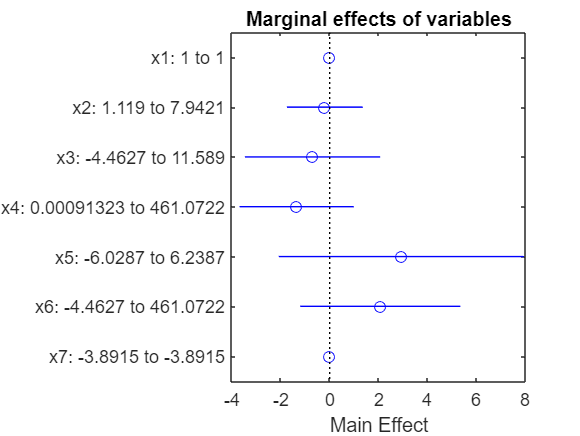

figure(30)
plotEffects(regresion)
title("Marginal effects of variables")
hold off

## Referencias

Greene (2016) Econometric Analysis. Pearson

Russell, K. G. (febrero de 1991). [«Estimating the Value of e by Simulation»](https://www.jstor.org/stable/2685243?seq=1#page_scan_tab_contents). *The American Statistician* **45** (1): 66-68.

[Learning Matlab using OLS](http://www.karenkopecky.net/Teaching/eco613614/Matlab%20Resources/OLS.pdf)